g = tf(-1.4479,[0.0401 1 0]);
g_ss = ss(g)


g_ss =
 
  A = 
           x1      x2
   x1  -24.94       0
   x2       1       0
 
  B = 
       u1
   x1   8
   x2   0
 
  C = 
           x1      x2
   y1       0  -4.513
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



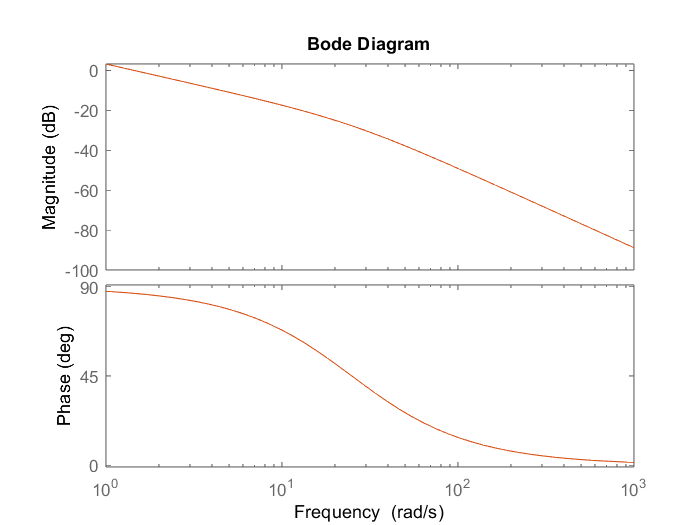


r =1;

J = (3.9e-7 + 7.06e-8 + 2.087e-3) + (1/r^2)*3.4950e-04;


La = 0.18e-3;
Km = 7.68e-3; % V/(rad/s)
Ra = 2.6;
P0 = 24.92;
P1 = 24.23;

beta0 = P0*J;
beta1 = P1*J;


A0 =g_ss.A;
A1 = g_ss.A;

B = g_ss.B;

C = g_ss.C;
D = [0];
Cf = [ 1 0 0; 0 1/r 0];

Plant0 = ss(A0,B,C,D);
bodeplot(Plant0)
hold on
bodeplot(g_ss)
hold off

Ob = obsv(A0,C);
rank(Ob) == 2

ans = logical
   1



Co = ctrb(A0,B);
rank(Co) == 2

ans = logical
   1


% cont PP
p = [24 2  ]

p =     24     2


K0 = place(A0,B,p)

K0 =    -6.3672    6.0000




% obs PP
Cf =[0, 1]

Cf =      0     1


L = place(A0',Cf',[-50-j*250  -50+j*250 ]*1)'

L = 	1.0e+04 *

    6.3128
    0.0075


At = A0-L*Cf;
Bt = [B,L];
Ct = diag([1  1]);
sysObserver0 = ss(At,Bt,Ct,0);
sysObserver0.InputName = {'u','y'};
sysObserver0.OutputName = {'y_hat','ome_hat'};